# INTRODUCTION TO MATLAB

## CHAPTER 2

### Function

Take a new script to write function, and save it into same directory.

factfor(5)

ans = 120

factwhile(4)

ans = 24

### [Solution of system by backslash operator](https://www.mathworks.com/help/matlab/ref/mldivide.html)

#### Example 2.1

The currents running through an electrical system are given by the following **system** of equations. The three currents,  x, y, and z, are measured in amps. **Write MATLAB codes** to solve the system by left division (**backslash**) operator. (Click on highlighted blue title to see web refference). 


$$\begin{array}{l}
8\textrm{𝑥}+3\textrm{𝑦}-5\textrm{𝑧}=3\\
\textrm{10𝑥}+7\textrm{𝑦}+2\textrm{𝑧}=4\\
\textrm{6𝑥}+4\textrm{𝑦}+7\textrm{𝑧}=8
\end{array}$$
        

% My code for suggestion, student may follow this, answer showed in right 
A = [8, 3, -5; 10, 7, 2; 6, 4, 7]

A =      8     3    -5
    10     7     2
     6     4     7


B = [3, 4, 8]'

B =      3
     4
     8


X = A\B

X =     1.7500
   -2.1829
    0.8902


## **CHAPTER 3**

### **Nonlinear Equations in One Variable**

#### **Example 3.1**

**(****a****) Find the number of real roots of **$x^3 +4x-3=0$** by graphical ****method**

**(b) ****Find the ****nmber**** of complex roots, if any.**

**(****c) Use MATLAB function “roots” to find all the roots including complex roots.**

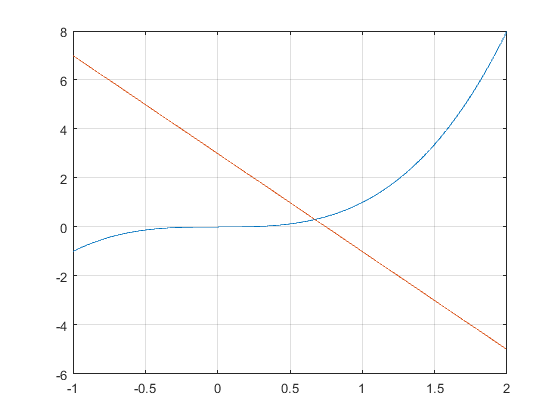

% (a) Let y1 = x^3 and y2 = 3-4x. Now let plot both in same frame
x = -1:.01:2;
y1 = x.^3;
y2 = 3-4*x;
plot(x,y1,x,y2);grid on

% (b) One real root, two complex roots
% (c) 
p = [1, 0, 4, -3]; % coefficient matrix
root = roots(p)

root =   -0.3368 + 2.0833i
  -0.3368 - 2.0833i
   0.6736 + 0.0000i


#### Example 3.2

Consider the function $f\left(x\right)=\mathrm{sin}\left(x\right)+3x-1$.

(a) Write MATLAB syntax for finding the root in [0, 1]  using MATLAB function “**fzero****”.**

(b)  Write MATLAB syntax for finding the root near $x=0\ldotp 5$ using MATLAB function “**fzero”.**

f = @(x) sin(x)+3*x-1;
solution1 = fzero(f,[0,1]) %(a)

solution1 = 0.2507

solution2 = fzero(f,0.5) %(b)

solution2 = 0.2507

## CHAPTER 4

### **Solution of System of Nonlinear Equations**

#### **Example 4.1**

Use MATLAB function “**fsolve(fun,x0)**” to find the solution of system at $\left(1\ldotp 5,-1\right)$.


$$\begin{array}{l}
x^2 +\mathrm{xy}-7=0\\
y^3 -2x+4=0
\end{array}$$


clear all
F = @(x) [x(1)^2 + x(1)*x(2) - 7; x(2)^3 - 2*x(1) + 4]; % function
x0 = [1.5; -1]; % initial values
sol = fsolve(F,x0) % solution


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


sol =     2.2698
    0.8141
